# Introduction to Plotting and Vectorization

## Student Information

Student Name: Qingyuan Wu

Student Number: 1007001664

## Exercise 1

Objective: Observe a MATLAB error when you try to access an invalid index.

Details: Try to access elements of the vector `x`, created in the previous step at the command prompt `>>`. Try values of `i` outside the valid range. Try negative values, zero, and large positive values. Copy down the error message in each case, and report this in your submitted work as:

% Only include the error message as a comment (with the percent signs), 
% DO NOT INCLUDE THE CODE IN YOUR SUBMISSION.

% Error for negative index:
%   x(-1)
%   Array indices must be positive integers or logical values.

% Error for zero index:
%   x(0)
%   Array indices must be positive integers or logical values.

% Error for positive index outside of the bounds:
%   x(10)
%   Index exceeds the number of array elements (6).

## Exercise 2

Objective: Create two vectors and plot one against the other.

Details: Explicitly create the vectors 

x = [-5, -3, -1, 0, 2, 4, 6] 

and 

y = [-25, -9, -1, 0, 4, 16, 36]

And plot `x` against `y`. Your submission should show both the creation of the vectors and the figure, as in the example.

x = [-5, -3, -1, 0, 2, 4, 6]

x =     -5    -3    -1     0     2     4     6


y = [-25, -9, -1, 0, 4, 16, 36]

y =    -25    -9    -1     0     4    16    36


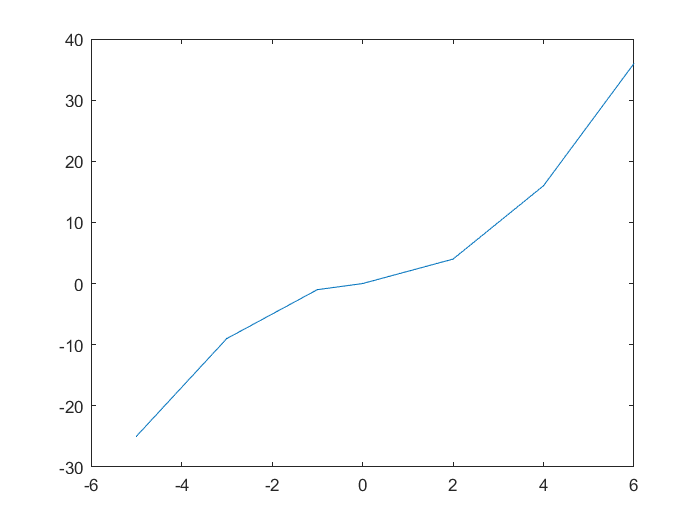

plot(x,y);

## Exercise 3

Objective: Plot `x`.x

Details: Using a for loop, create a vector x of 101 equally spaced points between -3 and 7, inclusive. Then create a vector y, such that `y(i) = abs(x(i))*x(i)` using a for loop. Plot the results. 

Your submission should include the code, as in the example, and appropriate comments.

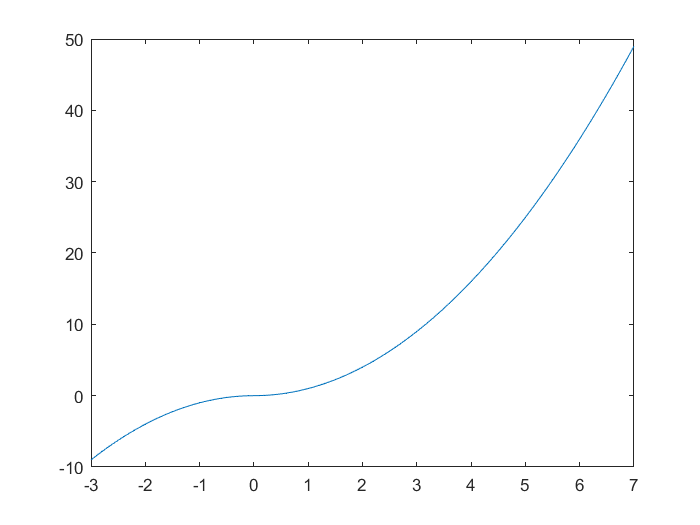

N = 101;

% preallocate x and y with zeros
x = zeros(N,1);
y = zeros(N,1);

% Variables for domain
start = -3;
endd = 7;

% calculate the increment
h = (endd-start)/(N-1);

% loop through to fill x and y values
for i = 1:N
    x(i) = start + h*(i-1);
    y(i) = abs(x(i)) * x(i); % modify the preallocated y array
end

plot(x,y); % plot the vectors as ordered pairs

## Exercise 4

Objective: Compare the speedup from vectorization for a larger vector.

Details: Create a vector `x` of 5000001 equally spaced points between -2 and 3, inclusive, using a for loop. Then time the construction of vector `y`, whose values are arctan of x, by a for loop and by vectorization. Be sure to clear  `y` between the two runs. (Hint: use the help file to find the command for arctan!)

Your submission should include the code, as in the example, with appropriate comments.

N = 5000001; % number of points to generate
start = -2; % interval is [-2, 3]
endd = 3;
h = (endd-start)/(N-1); % increment
x = zeros(5000001,1); % preallocate x with zeros

for i = 1:N % populate x
    x(i) = start + (i-1) * h;
end

tic % start timer
y = zeros(N,1);
for i = 1:N % generate y data using for loop
    y(i) = atan(x(i));
end
toc % end timer, display time

Elapsed time is 0.133264 seconds.



% "Elapsed time is 0.102163 seconds."

clear y;

tic % start timer
y = atan(x); % generate y data using vectorization
toc % end timer, display time

Elapsed time is 0.028637 seconds.



% "Elapsed time is 0.024718 seconds."

clear y;

## Exercise 5

Objective: Solve an ODE and plot three particular solutions.

Details: Manually find the general solution of the ODE:

dy/dt + (2*t)*y = 1/exp(t^2)

and the particular solutions for initial conditions y(1) = -1, y(1) = 0, and y(1) = 1. Plot these three particular solutions on the same axes lettting the independent variable range from 1 to 5. 

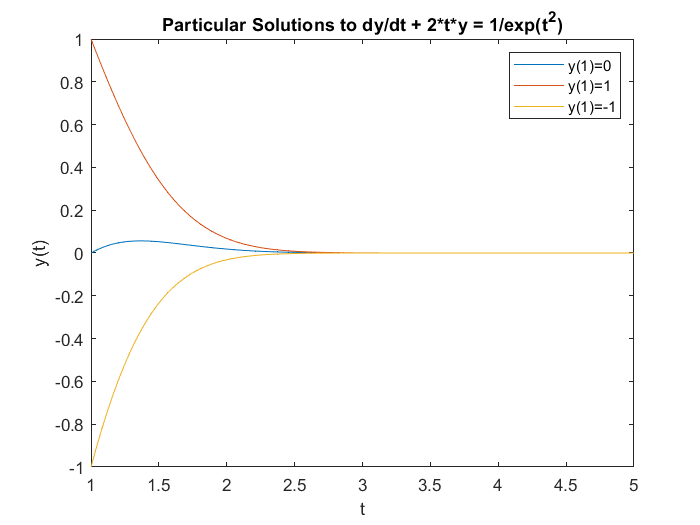

% general solution: y = (t+C)/exp(t^2), t = [1,5]
% y(1) = -1 => y = (t-e-1)/exp(t^2)
% y(1) = 0 => y = (t-1)/exp(t^2)
% y(1) = 1 => y = (t+e-1)/exp(t^2)

% Once you have the three particular solutions you will
% need to:
%
%  1. Create a vector for the independent variable, t.  Use linspace with
%  a reasonable number of points (100 is fine).
%  2. Create vectors for the three solutions.  Use vectorized operations.
%  3. Plot three solutions on the same axes, annotating the figure
%   appropriately.

% creating the t vector
t = linspace(1, 5, 100);

% creating the vectors for the particular solutions
y0 = (t-1)./exp(t.^2);
y1 = (t+exp(1)-1)./exp(t.^2);
y2 = (t-exp(1)-1)./exp(t.^2);

% plotting the particular solutions
plot(t, y0, t, y1, t, y2);

% labels and legend
xlabel("t");
ylabel("y(t)");
title("Particular Solutions to dy/dt + 2*t*y = 1/exp(t^2)");
legend("y(1)=0", "y(1)=1", "y(1)=-1");

% Your submission should include, in the description section, the general 
% solution of the ODE and the three particular solutions.  It should also 
% have the appropriately commented code.

## Exercise 6

Objective: Write and use an inline function of one variable.

Details: Define the inline function for

`f(x) = (x^3 - abs(x)) * ln(x^2+1)`

% defining the function
f = @(x) (x.^3 - abs(x)) .* log(x.^2+1);

% compute f(0), f(1), f(-1)
fprintf("f(%g) = %g\n", 0, f(0));

f(0) = 0


fprintf("f(%g) = %g\n", 1, f(1));

f(1) = 0


fprintf("f(%g) = %g\n", -1, f(-1));

f(-1) = -1.38629


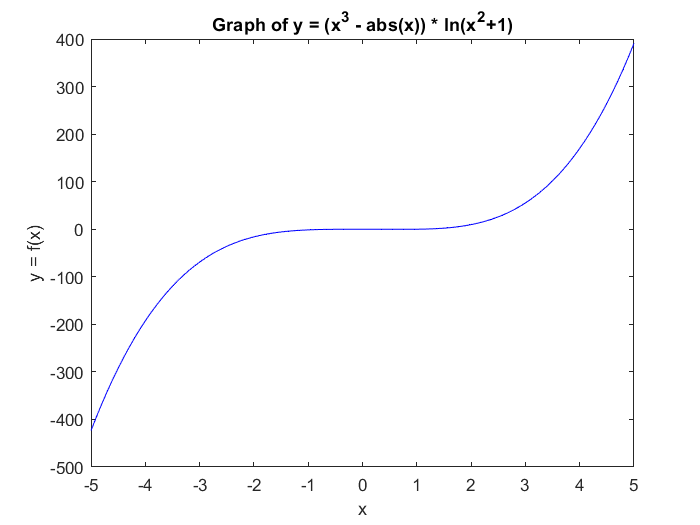


% 100 points in [-5, 5]
x = linspace(-5, 5, 100);

% plotting the function
plot(x, f(x), "b-");

% labels
xlabel("x");
ylabel("y = f(x)");
title("Graph of y = (x^3 - abs(x)) * ln(x^2+1)");


% Use this function to compute |f(0)|, |f(1)|, and |f(-1)| and plot the
% function with 100 grid points from -5 to 5. Make sure to
% use vectorization in your definition, and label your axes.
%
% Your submission should show the definition of the function, and the
% computation of these values.

## Exercise 7

Objective: Write and use an inline function of two variables.

Details: Define the inline function for

`f(x,y) = y + y^3 - cos x + x^2 - x^4`

f = @(x,y) y + y.^3 - cos(x) + x.^2 - x^4;

fprintf("f(%g, %g) = %g\n", 0, 0, f(0,0));

f(0, 0) = -1


fprintf("f(%g, %g) = %g\n", pi/2, 1, f(pi/2,1));

f(1.5708, 1) = -1.62067


fprintf("f(%g, %g) = %g\n", -1, -1, f(-1,-1));

f(-1, -1) = -2.5403


f(0,0)

ans = -1

f(pi/2,1)

ans = -1.6207

f(-1,-1)

ans = -2.5403

% Note that |f(x,y) = c| is the implicit solution to 
%
% |dy/dx = (4x^3 - 2x - sin x)/(1+3y^2)|.
%
% See Examples 1-3 of section 2.1 in Brannan and Boyce for similar examples.
%
% Use this function to compute |f(0, 0)|, |f(pi/2,1)|, and |f(-1,-1)|.  Make
% sure to use vectorization in your definition.
%
% Your submission should show the definition of the function, and the
% computation of these values.
%

## Exercise 8

Objective: Use fzero to solve an equation `f(x,y)=0` for y at different values of x.

Details: Consider the function

`f(x,y) = y + y^3 - cos x + x^2 - x^4`

% Define the inline function
f = @(x,y) y + y.^3 - cos(x) + x.^2 - x.^4;
x0 = 0;
guess = 0.5;
g = @(y) f(x0, y);
y = fzero(g, guess);
fprintf(' Solution for x = %g: y = %g\n', x0, y);

 Solution for x = 0: y = 0.682328



fprintf('---------------------------\n');

---------------------------



y0 = 1/2;
h = @(x) f(x, y0);

guess = 1;
x = fzero(h, guess);
fprintf(' Solution for y = %g: x = %g\n', y0, x);

 Solution for y = 0.5: x = 1.05844



guess = 0.5;
x = fzero(h, guess);
fprintf(' Solution for y = %g: x = %g\n', y0, x);

 Solution for y = 0.5: x = 0.567406



% Define the appropriate inline function and compute the single solution 
% at |x = 0| and the two positive solutions at |y = 1/2|.  
%
% You will need to experiment with different guesses to get these three
% solutions.
%
% Your submission should show the definition of the function, and the
% computation of these three roots.

## Exercise 9

Objective: Plot a portion of an implicit equation.

Details: Plot the portion of the solution to

`f(x,y) = y + y^3 - cos x + x^2 - x^4`

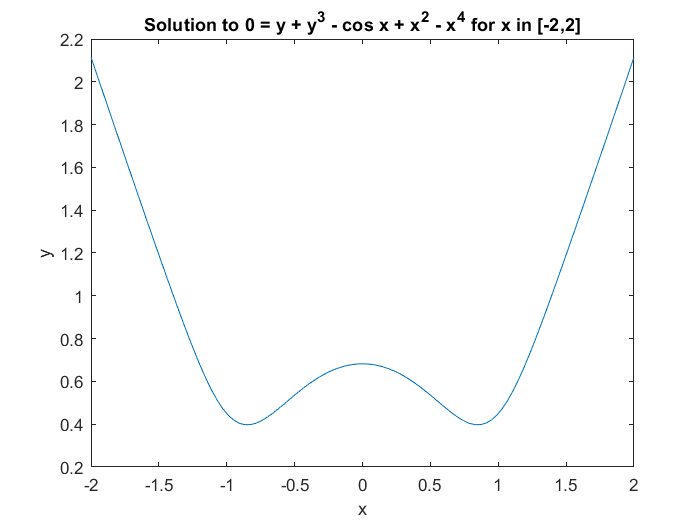

xvals = linspace(-2, 2, 100);
yvals = zeros(100,1);

f = @(x,y) y + y.^3 - cos(x) + x.^2 - x.^4;
for j = 1:length(xvals)
   h = @(y) f(xvals(j),y);
   % solve the implicit equation:
   yvals(j) = fzero(h, 0.5);
end

% Plot the results
plot(xvals, yvals);

% labels
xlabel("x");
ylabel("y");
title("Solution to 0 = y + y^3 - cos x + x^2 - x^4 for x in [-2,2]");


% passing through the point |(0,0)| for x from -2 to 2.  Use 100 grid
% points.
%
% You will need to be careful with the initial guess you use in solving the
% equation.
%
% Your submission should show the definition of the function, the
% construction of the arrays, the for loop, and the resultant figure.
%
% Label your axes.
%

## Exercise 10 - NOT FOR SUBMISSION

Objective: Solve a differential equation and plot a portion of it.

Details: Find the general implicit solution of the differential equation

`dy/dx = (-cos x + 3x^2) y` dy/y = (-cosx + 3x^2)dx % integrate both sides: ln(y) = -sinx + x^3 + C y = A*exp(-sinx + x^3) y(0) = 1 => A = 1 paricular sol'n: y = exp(-sinx + x^3)

% Plot the particular solution passing through y(0) = 1 using 100 grid
% points for x in [-1.5, 1.25].
%
% Be careful on your choice of guess. You will be penalized if MATLAB shows
% an error.
%
% Your submission should show the general and particular solutions, in
% implicit form, in the comments, the definition of the appropriate inline
% functions, arrays, the for loop, and the figure.
%
% Label your axes.

## Exercise 11

Objective: use iode a plot the direction field of a differential equation

Details: After starting iode, click the "direction fields" button from the main menu. The default is the direction field for

`dy/dx = sin(y-x)`

Click any point in the x-y plane to see a (numerically computed) solution to the differential equation passing through that point.

Starting from the "Equation" menu, plot the direction field of 

`dy/dx = xy^2`

% - Behaviour: all solutions are symmetric about the y-axis. Solutions with
% initial values above the x-axis tend to approach infinity. Solutions with
% initial values below the x axis tend to approach y=0.
% There is a semi-stable equilibrium at y=0:
% - As x approaches infinity, y approaches 0 for initial value <= 0; y
% appraoches infinity for initial value > 0.
% - The general solution to y' = xy^2 is y = -2/(x^2+C).
% From this we can conclude y(x) = y(-x) for all values of C. Therefore
% solutions to this ODE are symmetric about the y-axis.

% Describe, in words, the behaviour of the solutions. What happens as x
% approaches infinity? Explain why solutions are symmetric about the 
% y-axis, i.e. |y(x)=y(-x)| for any solution.

## Exercise 12

Objective: study the long-run behaviour of a differential equation from its direction field

Details: Using iode, plot the direction field of 

`dy/dx = y^4 - y^3 - 3*y^2 + y + 2`

By clicking on various initial conditions `y(0) = y_0` (iode plots the solution), determine the long-run behaviour of solutions as a function of `y_0`. In other words, list the constant solutions that are approached as x goes to infinity and how `y_0` determines which constant solution is approached.

% If your numerically computed solutions ever appear to cross then change
% the solution method from Euler to the, much better, Runge-Kutta method.
% Think about why solutions are not permitted to cross. If they do then
% this indicates a problem with the numerical solver.

% Equilibrium:
% There are three equilibria in the direction field, y=2, y=1, and y=-1.
% y=2 is an unstable equilibrium because the solutions diverge from y=2 as
% x approaches infinity.
% y=1 is a stable equilibrium because the solutions approach y=1 as x
% approaches infinity.
% y=-1 is a semi-stable equilibrium because solutions with initial values
% less than -1 eventually approach -1, but solutions with initial values
% greater than -1 diverge from -1.

% From observations: y(x0) = 2 will make the solution stablize at y = 2
% y(x0) > 2 will make the solution blow up to infinity
% -1 < y(x0) < 2 will make the solution approach 1
% y(x0) = -1 will make the solution stablizie at y = -1
% y(x0) < -1 will make the solution approach -1